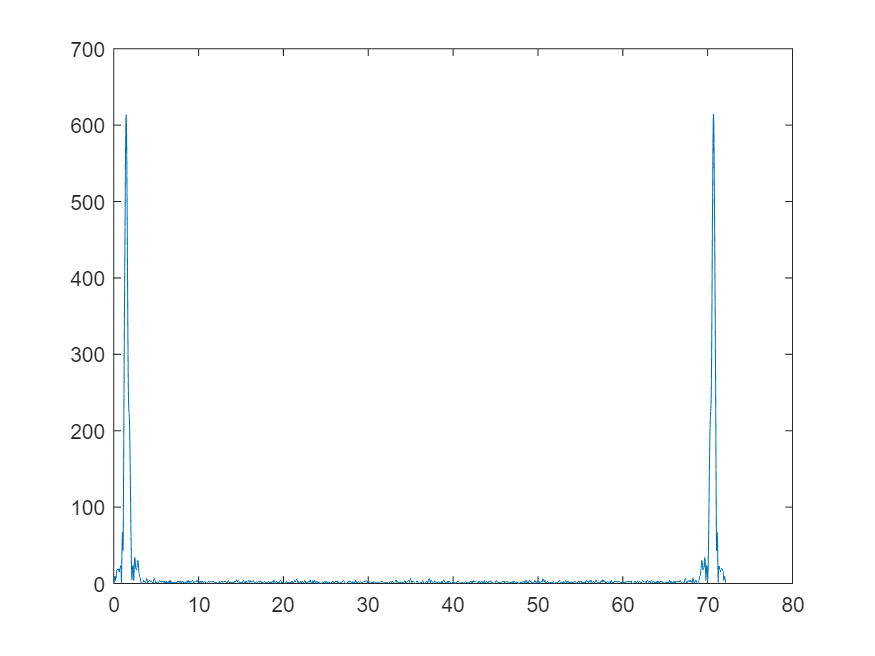

clear all; clc;
%-----------------------------------------------------------------------------------------------------
% 生成白光干涉信号
%显示光谱信息
format long
spectrum = readtable("Isigma.xls","ReadVariableNames",false);
spectrum_frequency = (spectrum{:,1})';
spectrum_intensity = (spectrum{:,2})';
%disp("全部光谱信息");
plot(spectrum_frequency,spectrum_intensity)

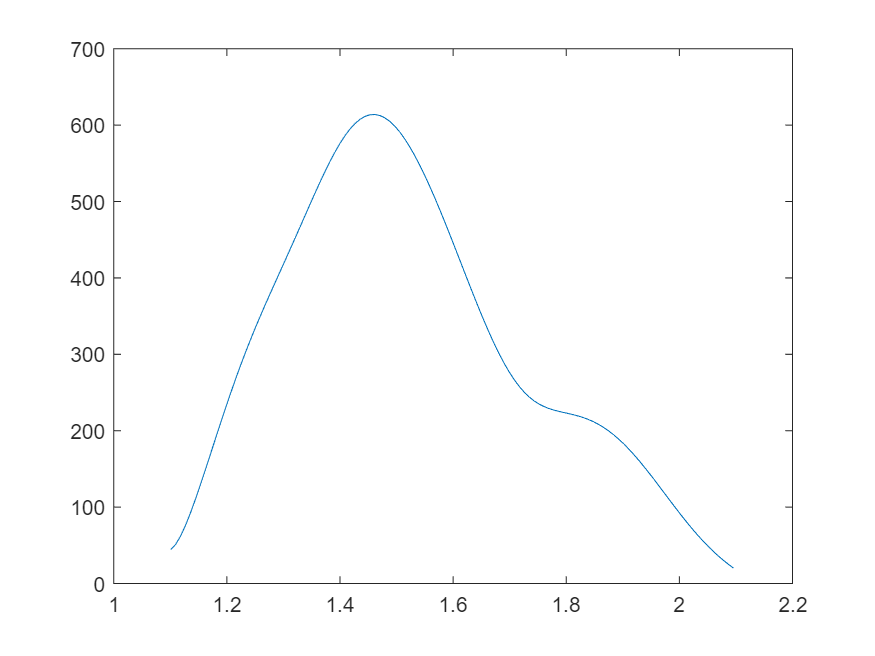

%找出探测器对应的光谱，这里假设是1.1-2.1
[~, indix_min] = min(abs(spectrum_frequency-1.1));
[~, indix_max] = min(abs(spectrum_frequency-2.1));
spectrum_frequency = spectrum_frequency(indix_min:indix_max);
spectrum_intensity = spectrum_intensity(indix_min:indix_max);
%disp("需要的光谱信息");
plot(spectrum_frequency,spectrum_intensity);

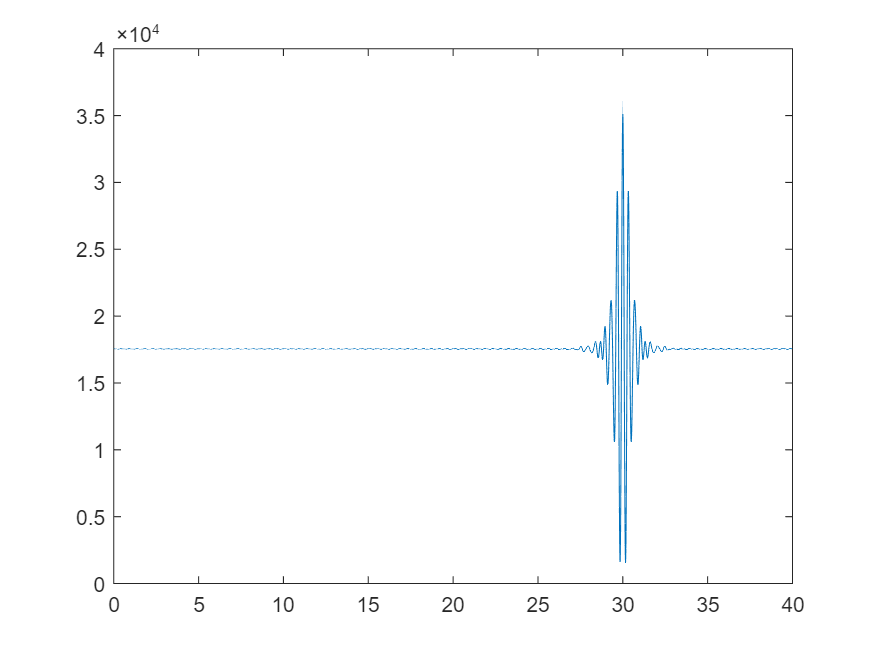

%生成白光干涉信号
z0 = 30;    %单位为微米
N = 4000;
z = 0:40/4000:(N-1)*(40/4000);
interference_signal = zeros(1,length(z));
for i = 1:length(z)
        interference_signal(i) = sum(spectrum_intensity./2+...
        spectrum_intensity./2.*cos(4*pi*(z(i)-z0).*spectrum_frequency));
end

%disp("生成的白光干涉信号");
plot(z,interference_signal);

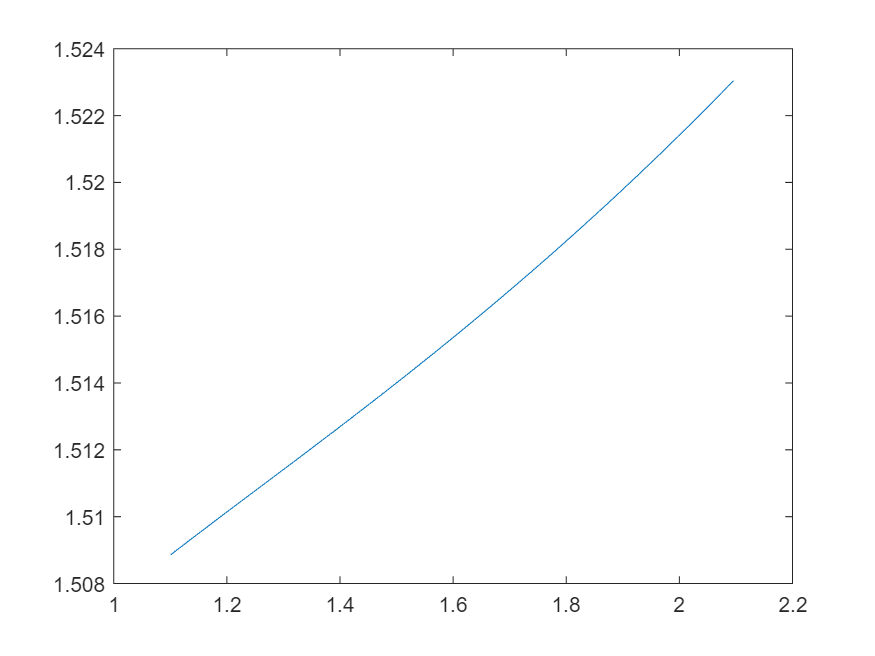

%-----------------------------------------------------------------------------------------------------
%对白光干涉信号进行傅里叶变换,由于直流项的存在，补零操作会导致频域震荡。
%滤除直流项
interference_signal = interference_signal-mean(interference_signal);
%fft补零
Nftt = 2^18;
f_interference_signal = fft(interference_signal,Nftt);
Fs = 1/(40/4000);
deltaSigma = Fs/(2*Nftt);
sigma = (0:Nftt/2)*deltaSigma;
% abs_fis = abs(f_interference_signal(1:Nftt/2+1))*2/Nftt;
ang_fis = angle(f_interference_signal(1:Nftt/2+1));
ang_fis = unwrap(ang_fis);
%对应频率1.1-2.1
[~, indix_min] = min(abs(sigma-1.2));
[~, indix_max] = min(abs(sigma-2.0));
%-----------------------------------------------------------------------------------------------------
%加入色散
%色散公式
lambda = 1./spectrum_frequency;
index2 = (1.03961212*lambda.^2)./(lambda.^2-0.00600069867)+(1.01046945*lambda.^2)./(lambda.^2-103.560653)+...
        (0.231792344*lambda.^2)./(lambda.^2-0.0200179144)+1; 
index = sqrt(abs(index2));
%折射率曲线
%disp("折射率曲线");
plot(spectrum_frequency,index);

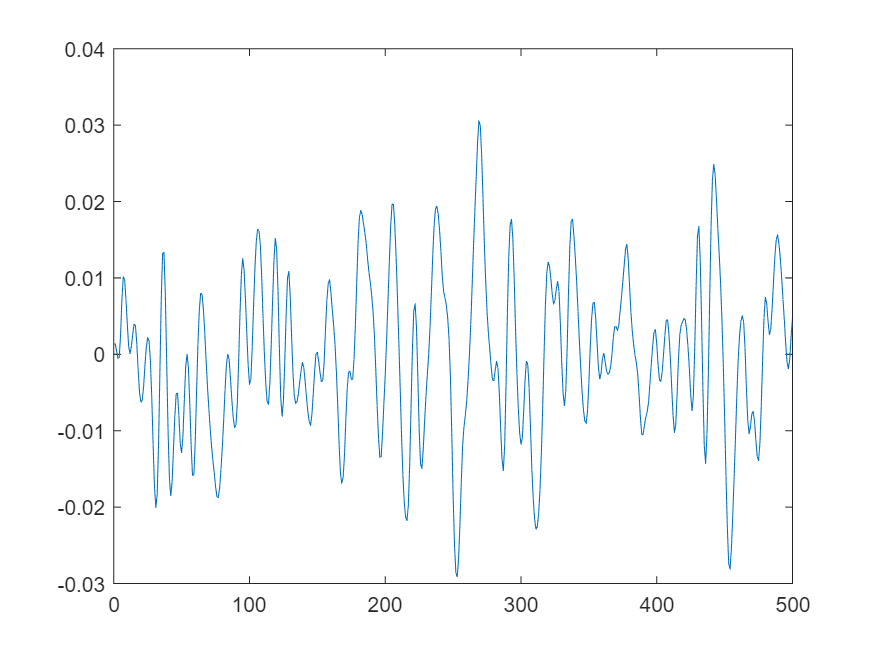

%色散
lEpsilon = 20; %单位为微米
N = 4000;
z = 0:40/4000:(N-1)*(40/4000);
interference_signal = zeros(1,length(z));
noise = gnoise(0,0.05,N);
% noise = normrnd(0,0.02,1,N);
for i = 1:length(z)
        interference_signal(i) = sum(spectrum_intensity./2+...
        spectrum_intensity./2.*cos(4*pi*(z(i)-z0+noise(i)).*spectrum_frequency+...
        4*pi*(index-1).*spectrum_frequency*lEpsilon));
end
plot(noise(1:500))

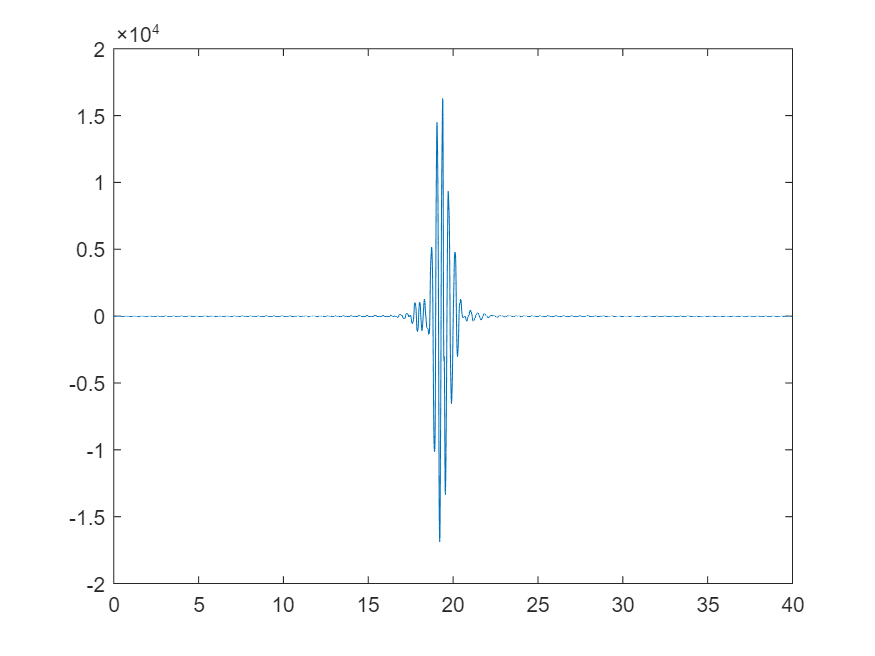

%-----------------------------------------------------------------------------------------------------
%傅里叶变换
%对白光干涉信号进行傅里叶变换,由于直流项的存在，补零操作会导致频域震荡。
%滤除直流项
interference_signal = interference_signal-mean(interference_signal);
plot(z,interference_signal);

function noise = gnoise(mean,std,N)
MU=mean;
SIGMA=std;
noise(1:N)=0;
corn=10;%%%180
han=hanning(corn);Extension=60;
han=han';
NOISE1=normrnd(MU,SIGMA,1,N+Extension);%NOISE2=normrnd(MU,SIGMA,1,N+Extension);
for no=1:N
ii=no;
noise(ii)=sum(han.*NOISE1(ii:ii+corn-1))/corn;%%%%100/24差不多4um不懂含义。。。。
end
end